# Laboratory 3

Problems

For the process described by Hf(s)=Kf/(s*Tfs+1), with Kf=2,Tf=5sec and the given performance indicators set, design the simplest controller possible using the dipole correction method. Demonstrate by plots that the imposed performance indicator set is met. 

clear variables;

estp = 0;
ts = 6; % < 8 sec
sigma = 4.25/100; % <= 10%
cv = 1.75; % >= 1.5
wb = 1.2; % wb <= 1.2rad/sec
ratio = 1.05;
sigmac = ratio-1;

Hf = tf(2,[5 1 0])

Hf =
 
      2
  ---------
  5 s^2 + s
 
Continuous-time transfer function.



zeta = abs(log(sigma))/sqrt(log(sigma)^2+pi^2);
wn = 4/ts/zeta;
pc = sigmac/(2*zeta/wn-1/cv)

pc = 0.0534

zc = pc/(1+sigmac)

zc = 0.0508

sigma_prim = sigma+sigmac;
Ho = tf([0 0 wn^2],[1 2*zeta*wn wn^2])*tf([pc,zc*pc],[zc,zc*pc])

Ho =
 
                0.04721 s + 0.0024
  ----------------------------------------------
  0.05085 s^3 + 0.07051 s^2 + 0.04858 s + 0.0024
 
Continuous-time transfer function.



Hr = (Ho/(1-Ho))/Hf

Hr =
 
   0.012 s^6 + 0.01965 s^5 + 0.01576 s^4 + 0.003612 s^3 + 0.0002587 s^2 + 5.762e-06 s
  -------------------------------------------------------------------------------------
  0.005171 s^6 + 0.01434 s^5 + 0.01502 s^4 + 0.007288 s^3 + 0.0004718 s^2 + 6.585e-06 s
 
Continuous-time transfer function.



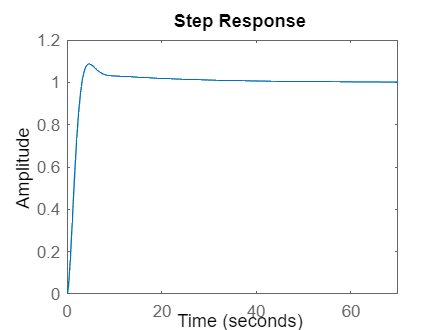


step(feedback(Hf*Hr,1))


cv = 1/(1/sigma/2/zeta-1/zc+1/pc)

cv = 0.0639

wb = wn*sqrt(1-2*zeta^2+sqrt(2-4*zeta^2+4*zeta^4))

wb = 0.9378